% rk4_internal_heat.m
clc;
clear;

% Parameters
T0 = 65;                    % Initial temperature
t0 = 0;                     % Initial time
tf = 24;                    % Final time
dt = 0.1;                   % Time step
N = floor((tf - t0)/dt);    % Number of steps

% Time vector
t = t0:dt:tf;
T = zeros(1, length(t));    % Preallocate solution
T(1) = T0;                  % Initial condition

% Define internal heat source H(t)
H = @(t) 7 * sech((3/4)*(t - 10));    % Heat from people/lights/machines
%       ^^^  Change first value to modify input heat sources

% Define derivative function dT/dt
dTdt = @(t, T) H(t);          % No losses, only accumulation

% RK4 Integration
for i = 1:N
    ti = t(i);
    Ti = T(i);

    k1 = dt * dTdt(ti, Ti);
    k2 = dt * dTdt(ti + dt/2, Ti + k1/2);
    k3 = dt * dTdt(ti + dt/2, Ti + k2/2);
    k4 = dt * dTdt(ti + dt, Ti + k3);

    T(i+1) = Ti + (1/6)*(k1 + 2*k2 + 2*k3 + k4);
end

% Find and display max temperature and when it occurs
[max_T, idx_max] = max(T);      % Max value and its index
time_max_T = t(idx_max);        % Time at which max occurs

fprintf('Maximum temperature: %.2f °F\n', max_T);

Maximum temperature: 94.31 °F


fprintf('Time of maximum temperature: %.2f hours\n', time_max_T);

Time of maximum temperature: 24.00 hours


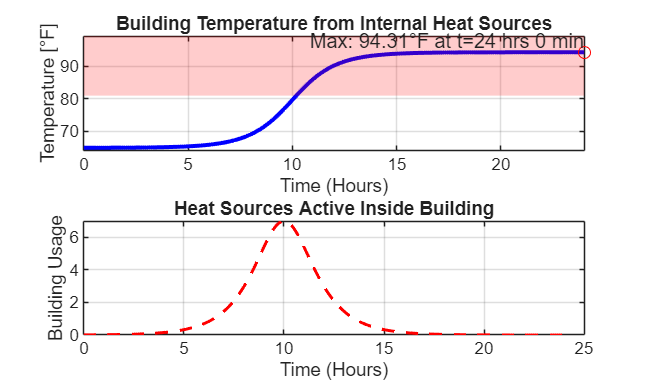


% Plot the result
figure;
y_max = max_T + 5; 

% Plot temperature T(t)
subplot(2, 1, 1);
plot(t, T, 'b-', 'LineWidth', 2);
xlabel('Time (Hours)');
ylabel('Temperature [°F]');
title('Building Temperature from Internal Heat Sources');
xlim([0 24]);        % Fix x-axis to 0–24 hours
ylim([min(T)-1, y_max]);  % Pad lower limit slightly for visibility
grid on;

% Add a red area to denote unsafe temps
hold on;
y_fill = 81 * ones(size(t));
y_max = max(T) + 5; 
fill([t, fliplr(t)], [y_fill, y_max * ones(size(t))], ...
     'r', 'FaceAlpha', 0.2, 'EdgeColor', 'none');
hold off;

% Add text to the graph where max temp occurs
hold on; % Keep the current plot
plot(time_max_T, max_T, 'ro'); % Mark the max temperature point
time_hours = floor(time_max_T); % Get the integer hours
time_minutes = round((time_max_T - time_hours) * 60); % Round minutes to nearest integer
text(time_max_T, max_T, sprintf('Max: %.2f°F at t=%d hrs %d min', max_T, time_hours, time_minutes), ...
    'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
hold off; % Release the plot

% Plot H(t) for comparison

%{
hold on;
plot(t, H(t), 'r--', 'LineWidth', 1.5);
legend('T(t)', 'H(t)');
%}

% Create a separate subplot for building usage
subplot(2, 1, 2);
plot(t, H(t), 'r--', 'LineWidth', 1.5);
xlabel('Time (Hours)');
ylabel('Building Usage');
title('Heat Sources Active Inside Building');
grid on;


% --- Helper function for sech ---
function y = sech(x)
    y = 1 ./ cosh(x);
end